# Sample 2-3

## 画像データの入出力

輝度値変換 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Input and output of images

Intensity transforms

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 処理画像の準備

(Preparation of sample image)

本サンプルで利用する画像データを収めたdata フォルダにパスをとおす。

Create a path to the data folder that contains images used in this sample.

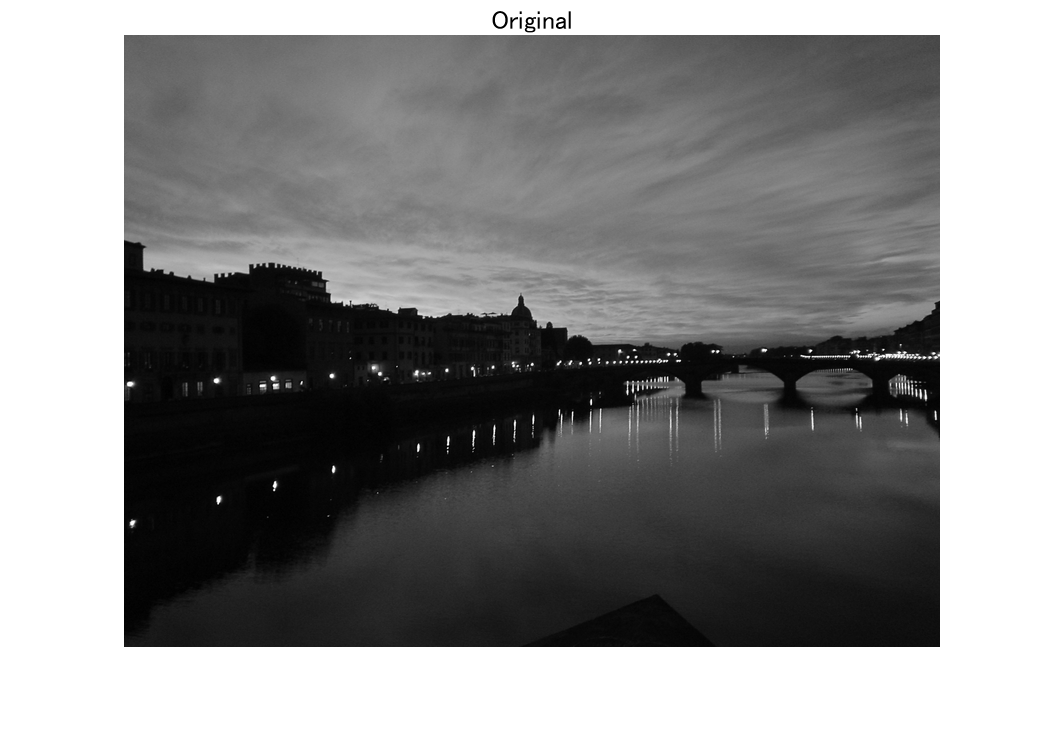

addpath('./data')
close
% Reading original image
I = im2double(rgb2gray(imread('firenzeRgb.jpg')));
imshow(I)
title('Original')

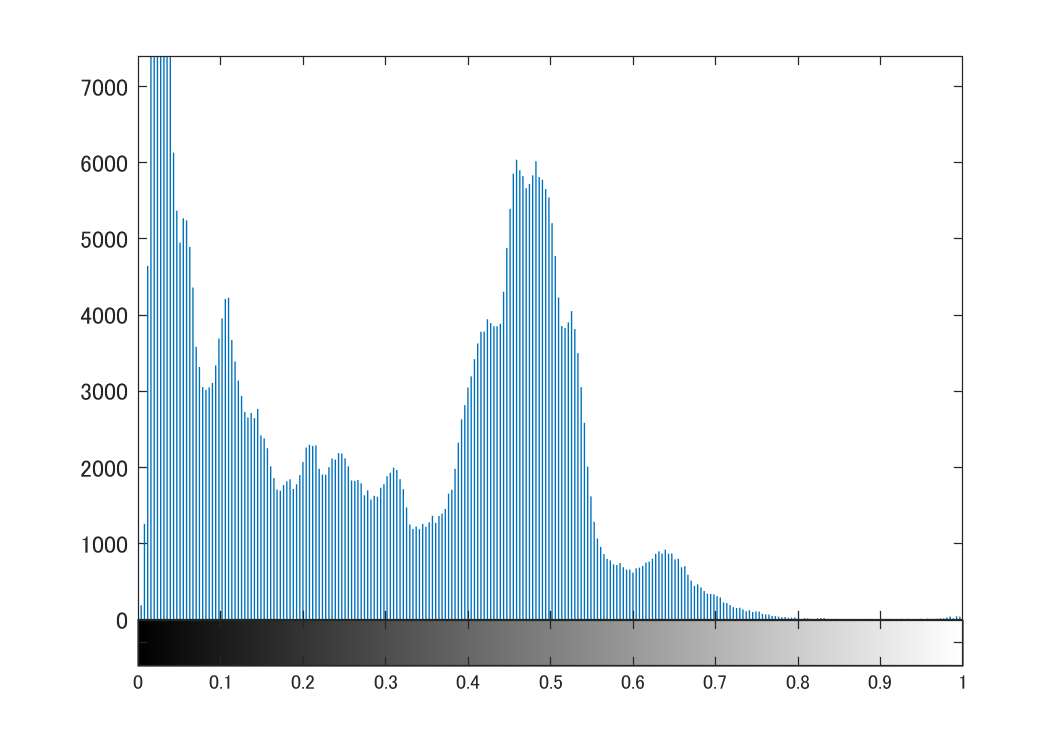

imhist(I)

### ネガ変換

(Negative conversion)


$$y=T(x) = 1.0-x$$


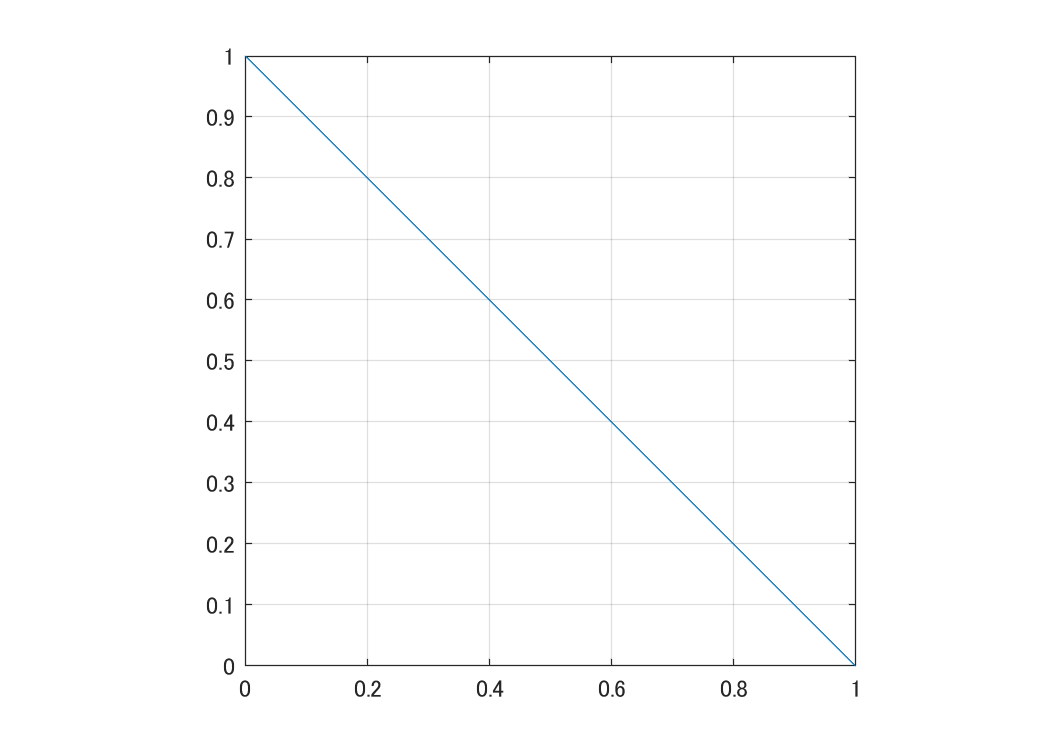

% Definition of negative conversion
Tn = @(x) 1.0-x;
fplot(Tn,[0,1])
axis square
grid on

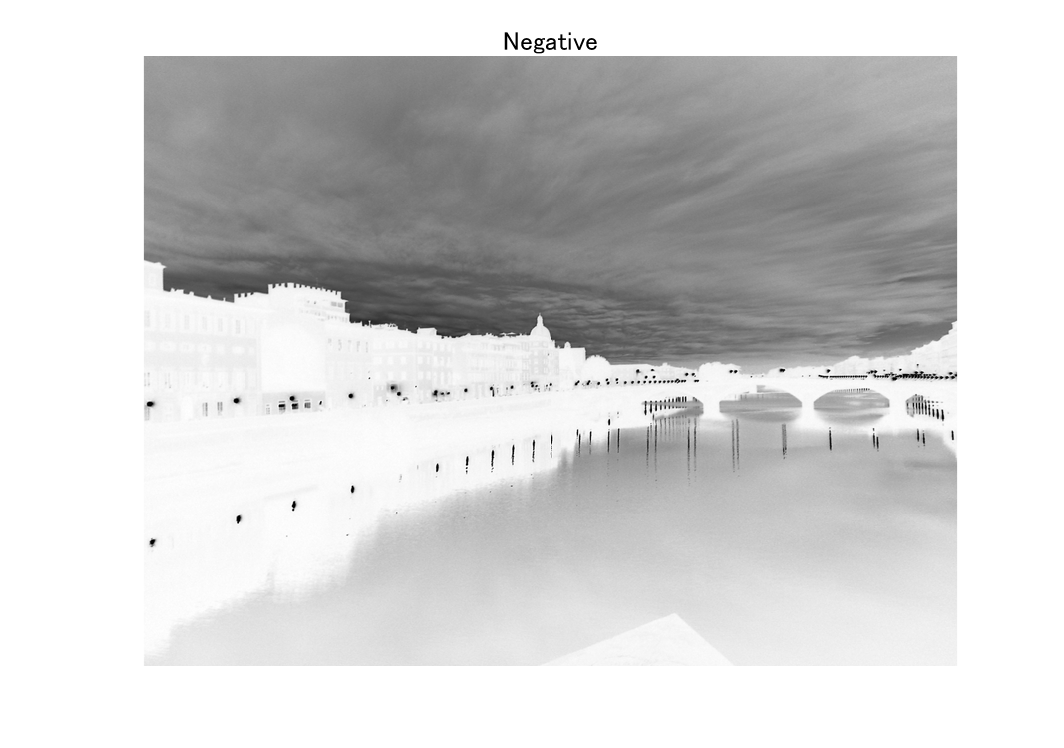

% Negative conversion of image I
J = Tn(I);
imshow(J)
title('Negative')

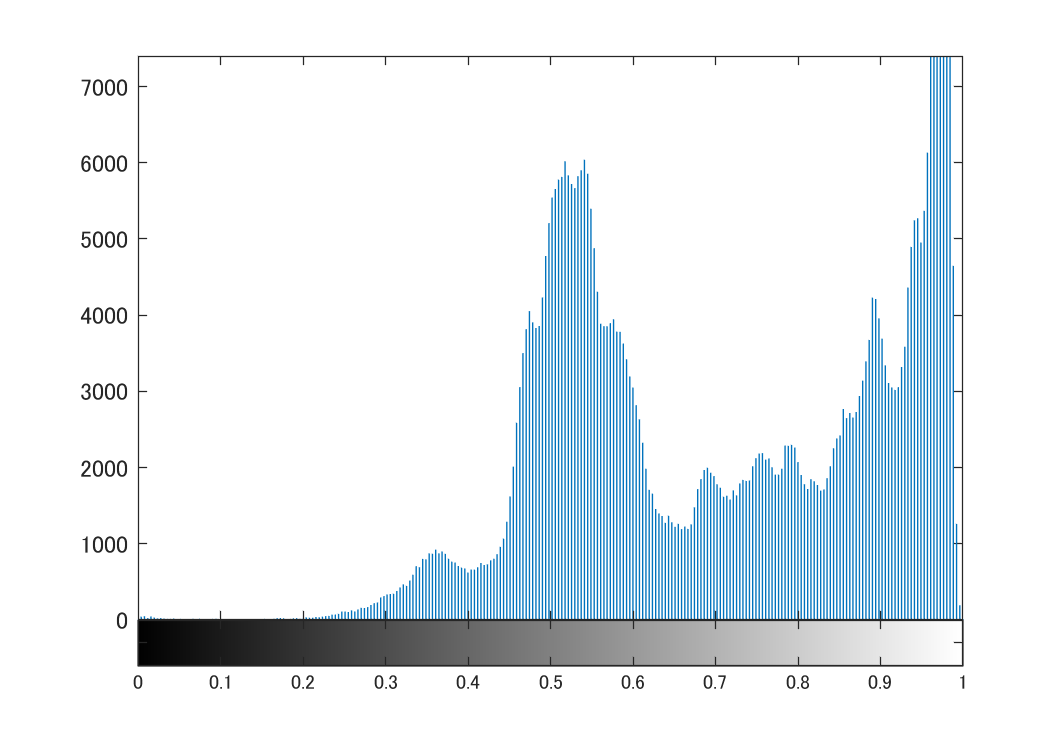

imhist(J)

### 対比伸長

(Contrast stretching)


$$y=T(x) = \frac{1}{2}(\mathrm{sign}(2x-1)|2x-1|^{10^{
-\alpha}}+1)$$


% Definition of contrast stretching
alpha = 1

alpha = 1

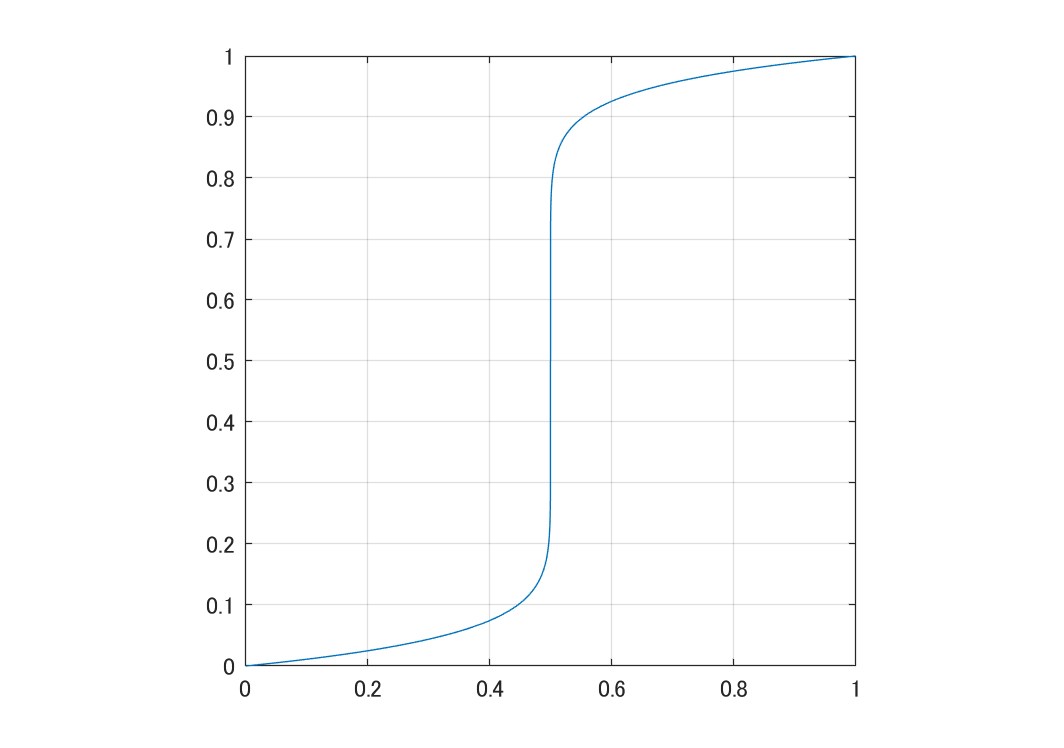

Tc = @(x) 0.5*(sign(2.0*x-1.0).*abs(2*x-1.0).^(10^(-alpha))+1.0);
fplot(Tc,[0,1])
axis square
grid on

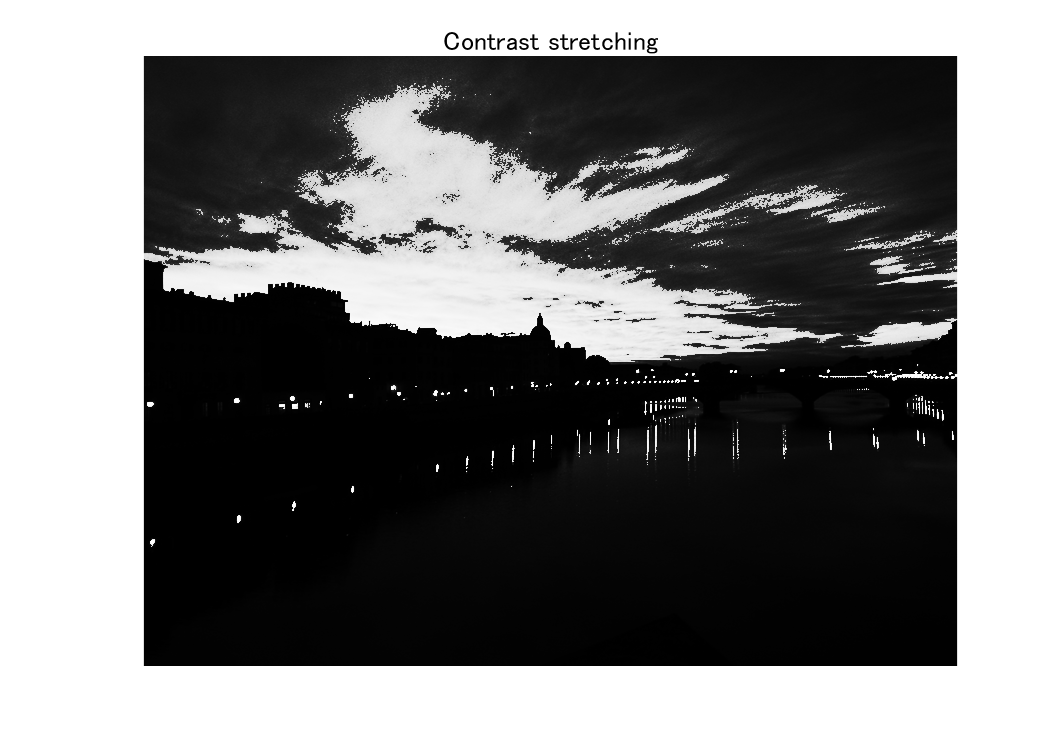

% Contrast stretching of image I
K = Tc(I);
imshow(K)
title('Contrast stretching')

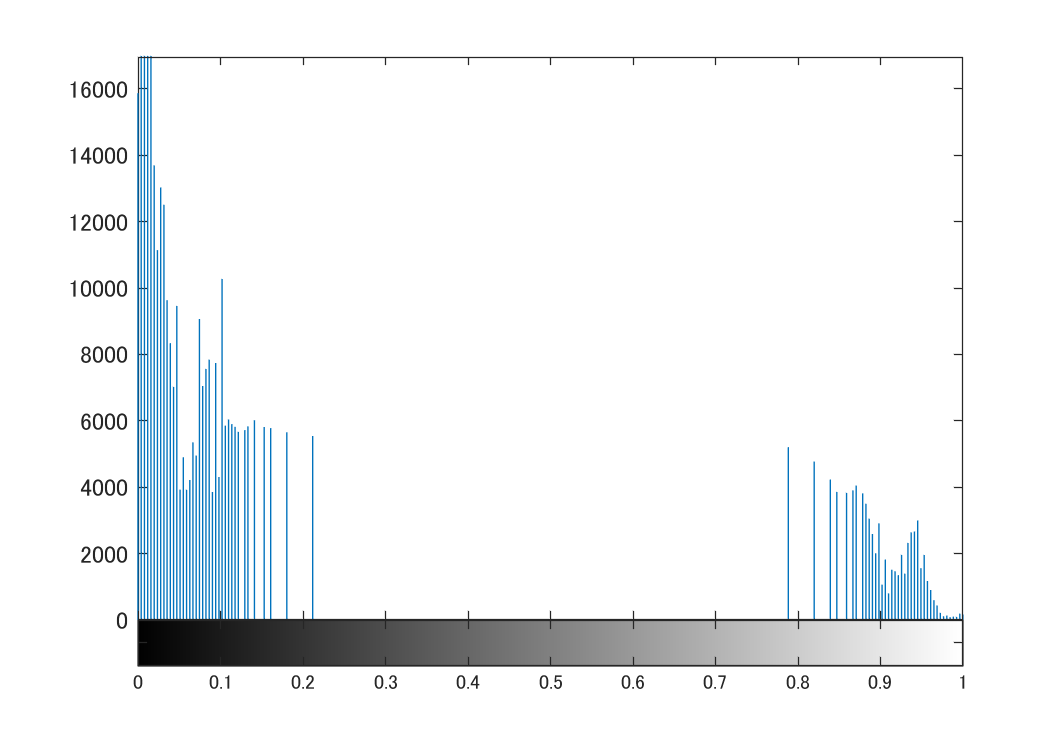

imhist(K)

### べき乗則変換

 (Power law conversion)


$$y=T(x) = x^\gamma$$
  

% Definition of power law conversion
gamma = 0.5

gamma = 0.5000

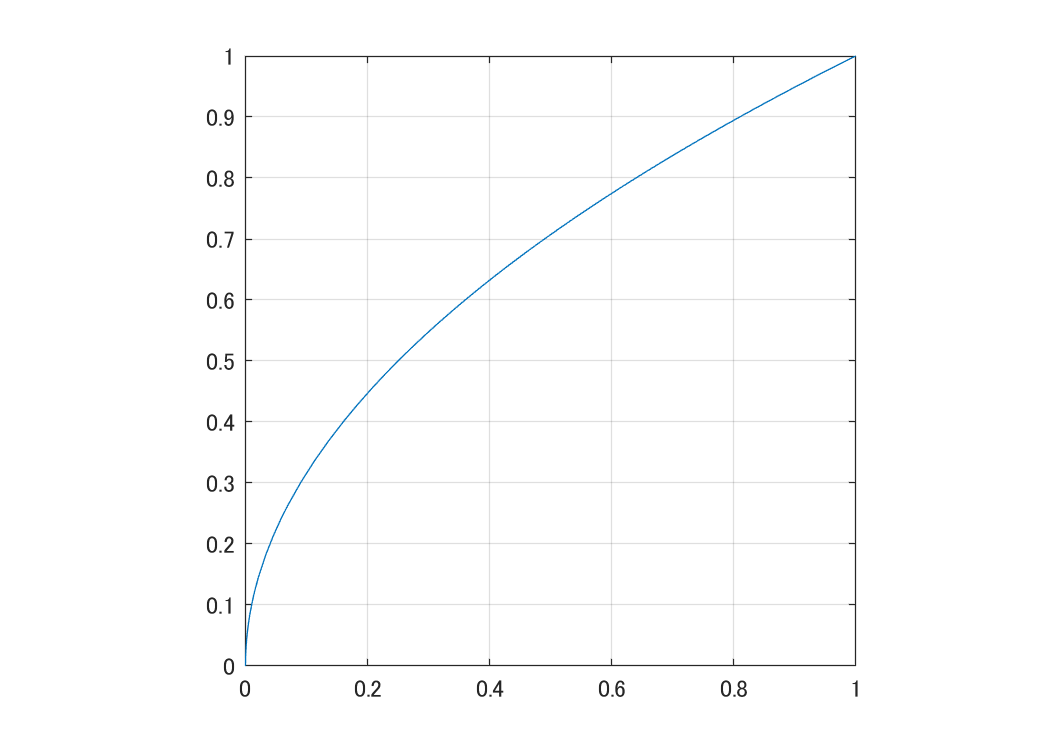

Tp = @(x) x.^gamma;
fplot(Tp,[0,1])
axis square
grid on

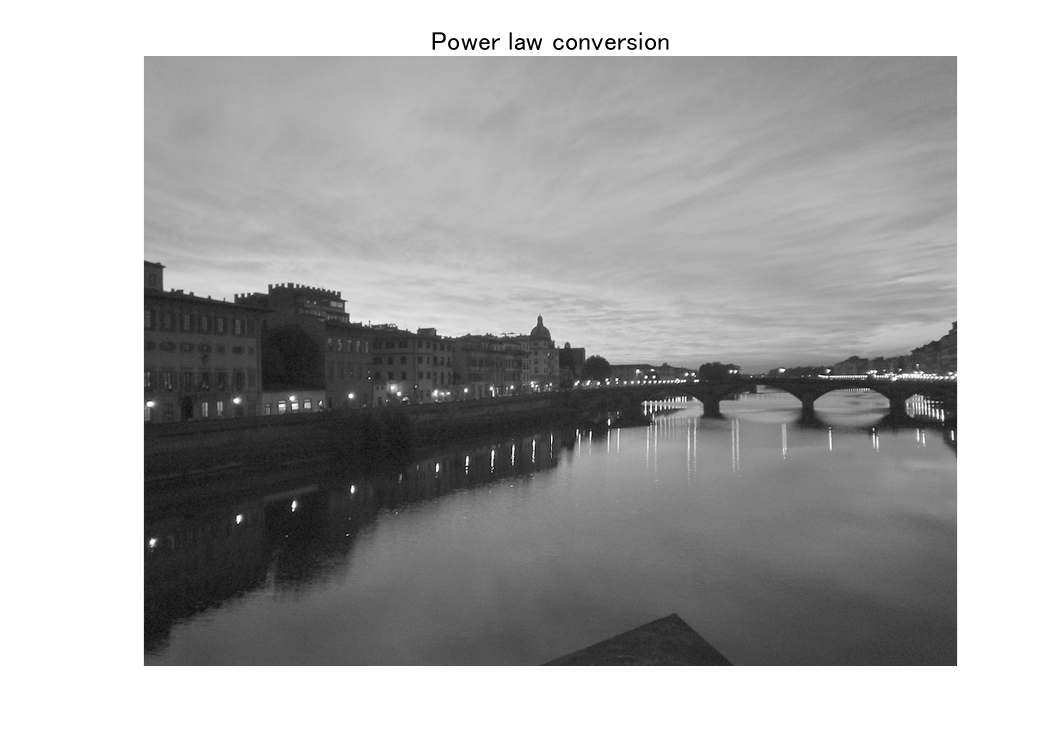

% Power law conversion of image I
L = Tp(I);
imshow(L)
title('Power law conversion')

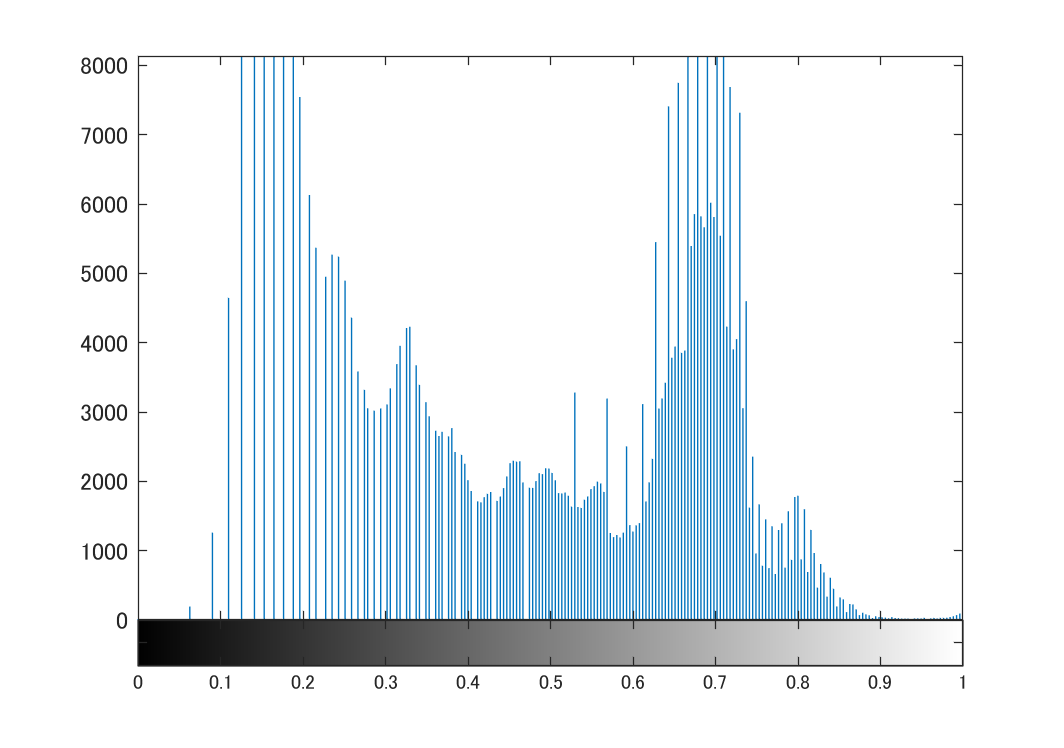

imhist(L)

### 輝度値調整関数

(Image adjustment function)

IMADJUST は高機能な輝度値調整関数で，uint8型画像に対してもべき乗測変換を含めた細かい調整が可能

IMADJUST is a sophisticated intensity adjustment function that allows fine tuning of images including uint8-type ones, such as power law conversion.

% Parameter setting of power law conversion
gamma = 0.5

gamma = 0.5000

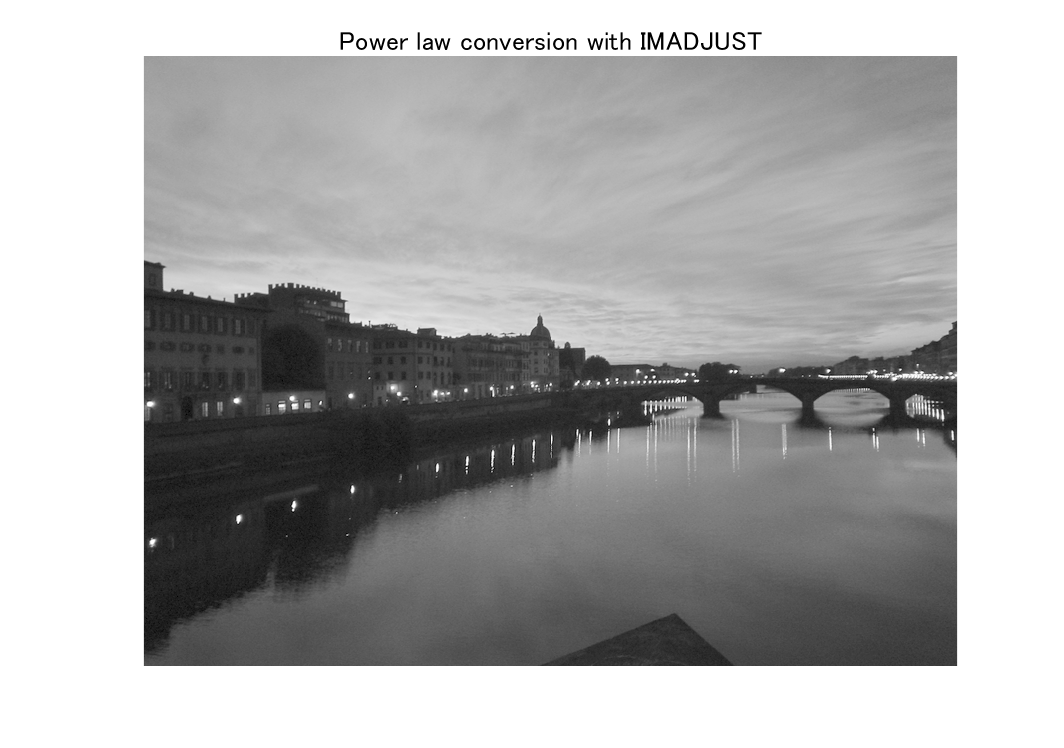

% Conversion to uint8
U = im2uint8(I);
% Power law conversion with IMADUST function
M = imadjust(U,[],[],gamma);
imshow(M)
title('Power law conversion with IMADJUST')

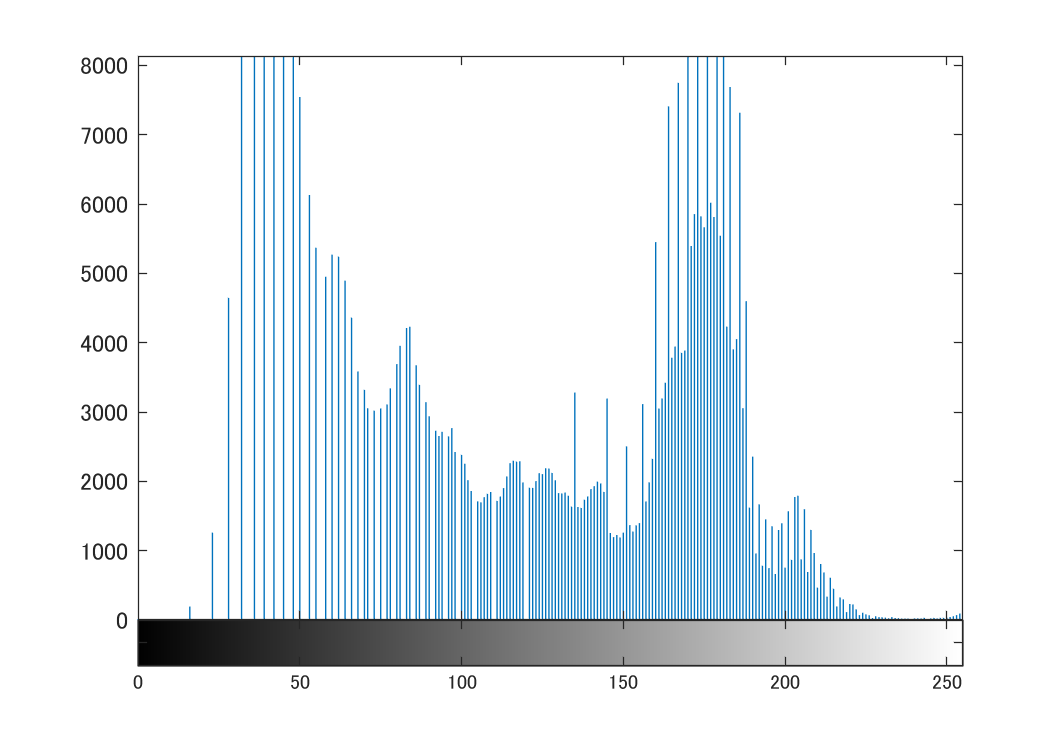

imhist(M)

© Copyright, Shogo MURAMATSU, All rights reserved.